clear
clear persistent
clc
rng(1)

% Pendulum
syms M_c m g l r b_v b_w real
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot

% Motor
syms J_m b_m real
syms tau

params = [M_c; m; g; l; r; b_v; b_m; J_m];
values = [0.3; 0.1; 9.82; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m + b_v*diff(x, t);

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = (M_c + J_m/r^2)*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
% and tau is motor reaction torque
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau - b_m*diff(x,t)/r;

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Nonlinear model
[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
accels = M \ rest;

f = formula([x_dot;
             theta_dot;
             accels(1);
             accels(2)]);

model = subs(f, formula(params), values);
pendulum_dynamics = matlabFunction(model, 'Vars', {x, theta, x_dot, theta_dot, tau});

% Linearized model

x_sym = formula([x; theta; x_dot; theta_dot]);
u_sym = tau;

op_state = [0; 0; 0; 0];
op_u = 0;

A_sym = jacobian(f, x_sym);
B_sym = jacobian(f, u_sym);

A_lin = subs(A_sym, [x_sym; u_sym], [op_state; op_u]);
B_lin = subs(B_sym, [x_sym; u_sym], [op_state; op_u]);

A = double(subs(A_lin, formula(params), values));
B = double(subs(B_lin, formula(params), values));
C = eye(4);

Ts = 0.01;

sys = ss(A,B,C,0);
dsys = c2d(sys, Ts);

Obsv = rank(obsv(sys));
Cont = rank(ctrb(sys));

Qx = [1, 0, 0, 0;
      0, 1, 0, 0;
      0, 0, 1, 0;
      0, 0, 0, 1];
Qu = 1;

[Kd, ~, ~] = dlqr(dsys.A, dsys.B, Qx, Qu);

% Check stability
eig(dsys.A - dsys.B*Kd);

% Simulate nonlinear system
t_end = 10;
T = 0:Ts:t_end;
x0 = [0; 0.3; 0; 0];
x = x0;

t_traj = [];
t_meas = [];
X = [];
X_filtered = [];
Y = [];
U = [];
 
% Assume zero mean measurement noise
% rough values:
sigma_x = 0.01*pi/(180*0.025)

sigma_x = 0.0070

sigma_th = 0.05*pi/180

sigma_th = 8.7266e-04

sigma_x_dot = 0.1*pi/(180*0.025)

sigma_x_dot = 0.0698

sigma_th_dot = 0.05*pi/180

sigma_th_dot = 8.7266e-04


sigma = [sigma_x; sigma_th; sigma_x_dot; sigma_th_dot]

sigma =     0.0070
    0.0009
    0.0698
    0.0009


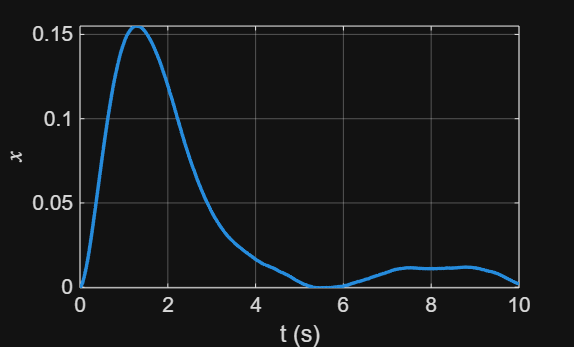

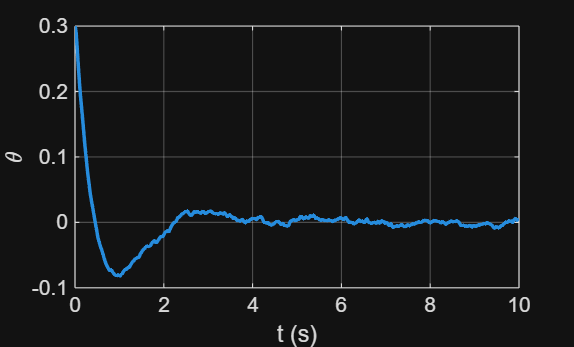

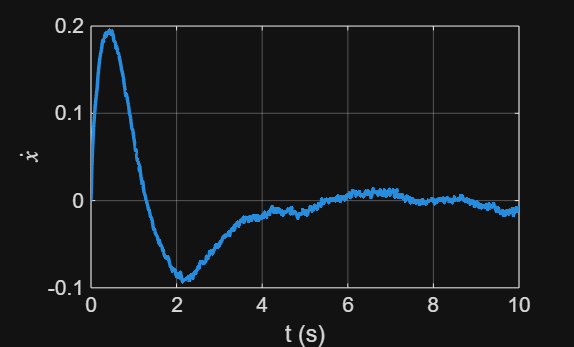

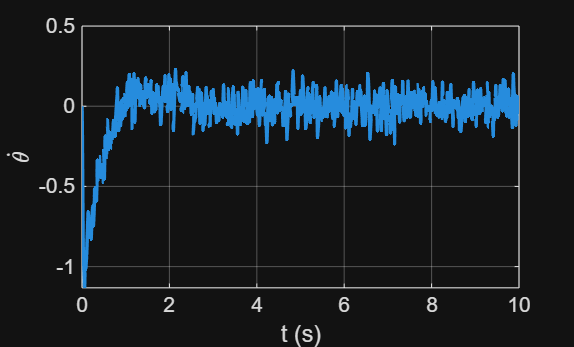


P0 = 1*eye(4);
Q = 0.05*eye(4);
H = C;
R = 0.05*eye(4);
u_prev = 0;

for k = 1:length(T)-1
    % Compute control at the start of interval from noisy measurment
    n = normrnd(0, sigma);
    y = x + n;

    x_filtered = kalmanFilter(y, H, R, x0, P0, dsys.A, Q, dsys.B, u_prev);
    u = -Kd*x_filtered;
    u_prev = u;
    
    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) pendulum_dynamics(x(1), x(2), x(3), x(4), u);

    [tk, xk] = ode45(ode, [T(k), T(k+1)], x); % Simulate from "true" state
    
    % Append trajectory
    t_traj = [t_traj; tk];
    X = [X; xk];
    
    % Store measurements
    t_meas = [t_meas; tk(1)];
    Y = [Y; y.'];
    U = [U; u*ones(length(tk),1)];
    X_filtered = [X_filtered; x_filtered.'];
    
    % Update state for next interval
    x = xk(end,:)';
end

%% Plots
states = ["$x$"; "$\theta$"; "$\dot{x}$"; "$\dot{\theta}$"];
for i = 1:size(X,2)
    figure;
    plot(t_traj, X(:,i), 'LineWidth',1.5);
    hold on
    % scatter(t_meas, Y(:,i), 5, 'filled');
    % plot(t_meas, X_filtered(:,i), 'LineWidth',1.5);

    xlabel('t (s)');
    ylabel(states(i),'Interpreter','latex');
    grid on;
    hold off
end

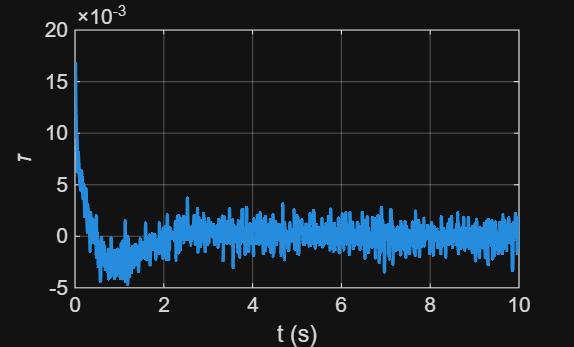


figure(2)
plot(t_traj, U, 'LineWidth',1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;